# **Detection and Estimation Theory**

**Final Project - Soroush Mesforush Mashhad - 810198472**

**Part 1 ) KF and Km plot (Fig3)**

clc
clear all
Td = 32;
Tc = 8;
Ts = Tc+Td;
M = 100*(Td+Tc);
M1 = Tc*M/Ts;
OFDMBW = 5e6;
Nc = 100;%Number of OFDM blocks

SNR_dB = linspace(-30,-10,Td);
Pd = 0.95;
Pfa = 1-Pd;
beta = Pfa;
A = (1-beta)/Pfa;
B = beta/(1-Pfa);
rho1 = zeros(length(SNR_dB),1);
for i=1:length(SNR_dB)
    rho1(i) = (Tc)/(Td+Tc)*(db_to_lin(SNR_dB(i)))/(1+db_to_lin(SNR_dB(i)));
end
ELn_H0 =  zeros(length(SNR_dB),1);
ELn_H1 =  zeros(length(SNR_dB),1);
for i=1:length(SNR_dB)
    ELn_H0(i) = -M.*log10(1-rho1(i)^2)-2*M*((rho1(i)^2)/(1-rho1(i) ^ 2));
    ELn_H1(i) = -M.*log10(1-rho1(i)^2);
end

EKs_H0 =  zeros(length(SNR_dB),1);
EKs_H1 =  zeros(length(SNR_dB),1);

for i=1:length(SNR_dB)
   EKs_H0(i) = (Pfa.*log10(A)+(1-Pfa).*log10(B))./( ELn_H0(i));
   EKs_H1(i) = ( (1-beta).*log10(A) + beta.*log10(B))/(ELn_H1(i));
end
Km = max( EKs_H0,EKs_H1);

Kf = zeros(length(SNR_dB),1);
for i=1:length(SNR_dB)
    Kf(i) = (erfcinv(2*Pfa) - (1-rho1(i).^2).*erfcinv(2*Pd) ).^2./(M*rho1(i) .^ 2);
end

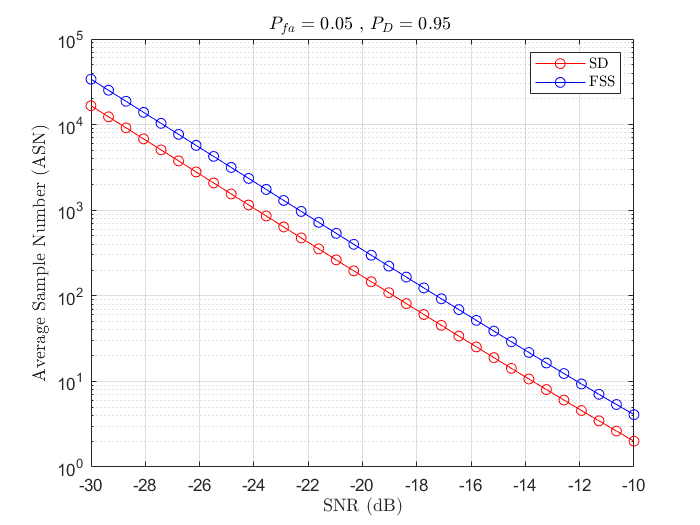

figure
semilogy(SNR_dB,Km,'r-o',SNR_dB,Kf,'b-o')
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("Average Sample Number (ASN)",'interpreter','latex');
title(" $P_{fa} = 0.05$ , $P_D = 0.95$ ",'interpreter','latex');
legend('SD','FSS','interpreter','latex')

**Part 2) Fig4**

**Theoretical**

SNR_dB = -10;
SNR = db_to_lin(SNR_dB);
rho1 = (Tc)/(Td+Tc)*((SNR)/(SNR+1));
Pfa = linspace(-1,1,1000);
etal = zeros(length(Pfa),1);
for i=1:length(Pfa)
    etal(i) =(1/sqrt(M)).*erfcinv(2.*Pfa(i));
end
Pd = 0.5.*erfc(sqrt(M).*(etal - rho1/(1-rho1 .^2)));

figure
plot(Pfa,Pd)
grid on
xlabel(" Probability of False Alarm ($P_{fa}$)",'interpreter','latex');
ylabel("Probability of Detection ($P_D$)",'interpreter','latex');
title(" ROC Plot for $ SNR = -10dB$ ",'interpreter','latex');

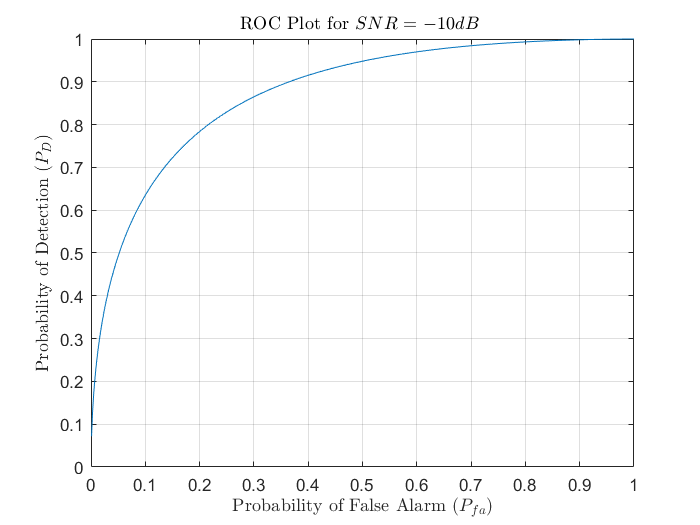

Nc = 100;       
Td = 32;          

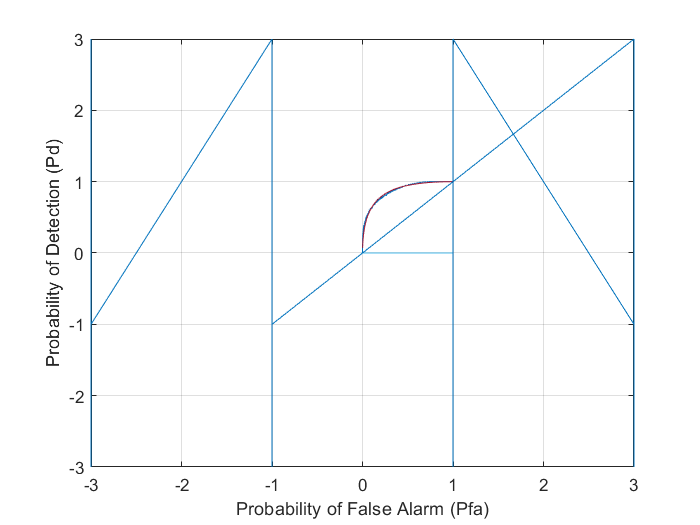

Tc = 8;     
Ts = Td + Tc;
N = Td * Nc;
Mod = 16;                 
k = log2(Mod);
SNR_dB = -10;        
Pfasim = linspace(0,1,1000);
Pdsim = zeros(1000);
data = randi([0, 1], k*N, 1);
dataSymbols = reshape(data, k, []).';
constellation = qammod(0:Mod-1, Mod);
x = constellation(bin2dec(num2str(dataSymbols))+1);
x = reshape(x, Td, Nc);
xifft = ifft(x, Td);
xifftwithcp = [xifft(end-Tc+1:end, :); xifft];
xsend = xifftwithcp(:);

N0 = 1/(2*db_to_lin(SNR_dB))
thresh = erfcinv(2.*Pfasim).*1.3*N0+2.9
for i = 1:length(Pfasim)
    noise = sqrt(N0/2) * (randn(size(xsend)) + 1j * randn(size(xsend)));

N0 = 5

    y = xsend + noise;

thresh =        Inf   17.1019   16.1271   15.5278   15.0879   14.7374   14.4447   14.1924   13.9702   13.7711   13.5906   13.4252   13.2724   13.1303   12.9974   12.8723   12.7543   12.6424   12.5360   12.4346   12.3375   12.2445   12.1552   12.0693   11.9864   11.9064   11.8290   11.7541   11.6815   11.6110   11.5425   11.4758   11.4109   11.3477   11.2860   11.2258   11.1670   11.1095   11.0533   10.9983   10.9444   10.8915   10.8398   10.7890   10.7391   10.6902   10.6421   10.5949   10.5484   10.5028


    yCP = reshape(y, Ts, []);
    y = yCP(Tc+1:end, :);
    Y = fft(y, Td);
    Y = Y(:);
    detections = sum(abs(Y) > thresh(i));%1.9*qfuncinv(Pfasim(i)) *  noiseVar^0.5+2.9);
    Pdsim(i) = detections / (N);
end
figure;
plot(Pfasim, Pdsim);
hold on
plot(Pfa,Pd)
xlabel('Probability of False Alarm (Pfa)');
ylabel('Probability of Detection (Pd)');
%title(['Receiver Operating Characteristic (ROC) Curve for OFDM System at SNR = ' num2str(EbNo) ' dB']);
grid on;

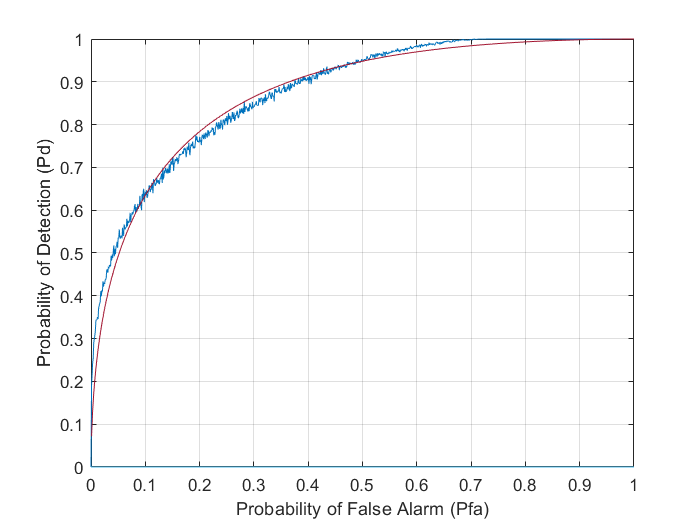

Nc = 100;       
Td = 32;          
Tc = 8;     

Ts = Td + Tc;
N = Td * Nc;
Mod = 16;                 
k = log2(Mod)
SNR_dB = -10;        
Pfasim2 = linspace(0,1,1000)
Pdsim2 = zeros(1000);
data = randi([0, 1], k*N, 1);

k = 4

dataSymbols = reshape(data, k, []).';
constellation = qammod(0:Mod-1, Mod);

Pfasim2 =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


x = constellation(bin2dec(num2str(dataSymbols))+1);
x = reshape(x, Td, Nc);
xifft = ifft(x, Td);
xifftwithcp = [xifft(end-Tc+1:end, :); xifft];
xsend = xifftwithcp(:);
N0 = 1/(2*db_to_lin(SNR_dB));                         
sigma_shadowing = 5;
thresh = erfcinv(2.*Pfasim).*1.3*N0+2.9
% Generate shadowing component
shadowing_dB = randn(size(xsend)) * sigma_shadowing;
shadowing = 10.^(shadowing_dB/10);
for i = 1:length(Pfasim2)

thresh =        Inf   17.1019   16.1271   15.5278   15.0879   14.7374   14.4447   14.1924   13.9702   13.7711   13.5906   13.4252   13.2724   13.1303   12.9974   12.8723   12.7543   12.6424   12.5360   12.4346   12.3375   12.2445   12.1552   12.0693   11.9864   11.9064   11.8290   11.7541   11.6815   11.6110   11.5425   11.4758   11.4109   11.3477   11.2860   11.2258   11.1670   11.1095   11.0533   10.9983   10.9444   10.8915   10.8398   10.7890   10.7391   10.6902   10.6421   10.5949   10.5484   10.5028


    noise = sqrt(N0/2) * (randn(size(xsend)) + 1j * randn(size(xsend)));
    y = xsend.*shadowing + noise;
    yCP = reshape(y, Ts, []);
    y = yCP(Tc+1:end, :);
    Y = fft(y, Td);
    Y = Y(:);
    detections = sum(abs(Y) > thresh(i));%1.9*qfuncinv(Pfasim(i)) *  noiseVar^0.5+2.9);
    Pdsim2(i) = detections / (N);
end
figure;
plot(Pfasim, Pdsim);
hold on
plot(Pfasim2,Pdsim2)
xlabel('Probability of False Alarm (Pfa)');
ylabel('Probability of Detection (Pd)');
%title(['Receiver Operating Characteristic (ROC) Curve for OFDM System at SNR = ' num2str(EbNo) ' dB']);
grid on;

**Part 2) Fig 5**

**CP Unknown**

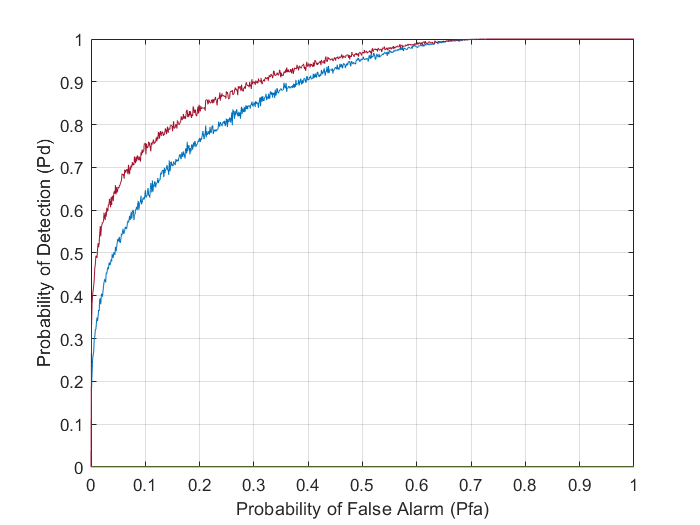

 clc
 clear all
 Td = 32;
 Tc = 8;

 Ts = Tc+Td;
 M = 100*(Td+Tc);
 M1 = Tc*M/Ts;
 OFDMBW = 5e6;
Nc = 100;%Number of OFDM blocks

SNR_dB = linspace(-25,-0,Td);
Pfa = 0.05;
rho1 = zeros(length(SNR_dB),1);
for i=1:length(SNR_dB)
    rho1(i) = (Tc)/(Td+Tc)*(db_to_lin(SNR_dB(i)))/(1+db_to_lin(SNR_dB(i)));
end
 etal =(1/sqrt(M)).*erfcinv(2.*Pfa);
 Pdcpunknowntheory = zeros(length(SNR_dB),1);
 for i=1:length(SNR_dB)
     Pdcpunknowntheory(i) = 0.5.*erfc(sqrt(M).*(etal - rho1(i)/(1-rho1(i) .^2)));
 end
 

figure
plot(SNR_dB,Pdcpunknowntheory)
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("Probability of Detection ($P_D$)",'interpreter','latex');
title(" $P_d$ vs SNR for $ P_{fa} = -10dB$ CP unknown ",'interpreter','latex');

**Simulation**

**CP Known**

**Theory**

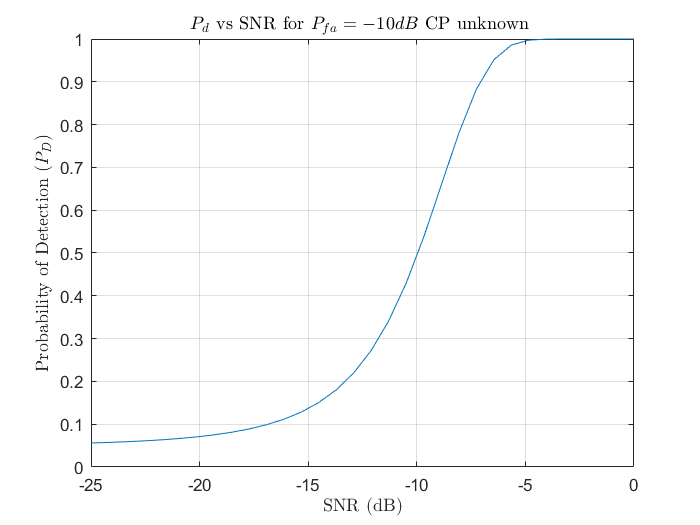

SNR_dB = linspace(-25,-0,Td);
Pfa = 0.05;
rhoc = zeros(length(SNR_dB),1);
for i=1:length(SNR_dB)
    rhoc(i) = (db_to_lin(SNR_dB(i)))/(1+db_to_lin(SNR_dB(i)));
end
 etal =(1/sqrt(M1)).*erfcinv(2.*Pfa);
 Pdcpknowntheory = zeros(length(SNR_dB),1);
 for i=1:length(SNR_dB)
     Pdcpknowntheory(i) = 0.5.*erfc(sqrt(M1).*(etal - rhoc(i)/(1-rhoc(i) .^2)));
 end

figure
plot(SNR_dB,Pdcpknowntheory)
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("Probability of Detection ($P_D$)",'interpreter','latex');
title(" $P_d$ vs SNR for $ P_{fa} = -10dB$ CP known ",'interpreter','latex');

figure
plot(SNR_dB,Pdcpknowntheory,SNR_dB,Pdcpunknowntheory)
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("Probability of Detection ($P_D$)",'interpreter','latex');
title(" $P_d$ vs SNR for $ P_{fa} = -10dB$ CP known and unknown ",'interpreter','latex');
legend('CP Known','CP unknown')

**Simulation**

**Part 4) Fig 8**

**Theory**

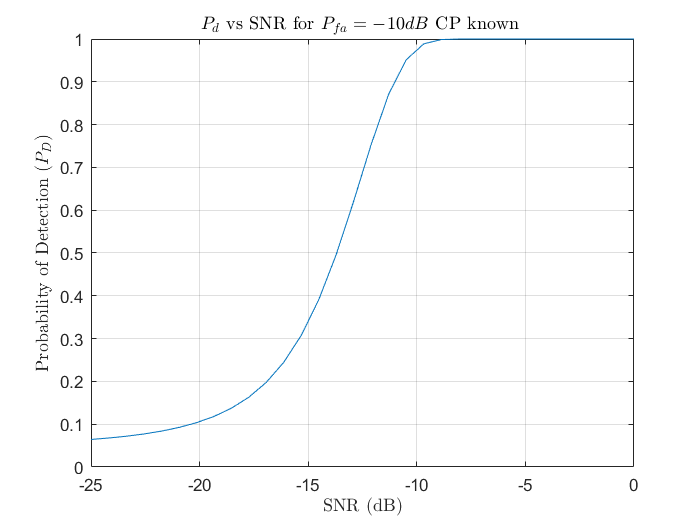

SNR_dB = linspace(-20,-10,Td);
Pd = 0.95;
Pfa = 1-Pd;
beta = Pfa;
A = (1-beta)/Pfa;
B = beta/(1-Pfa);

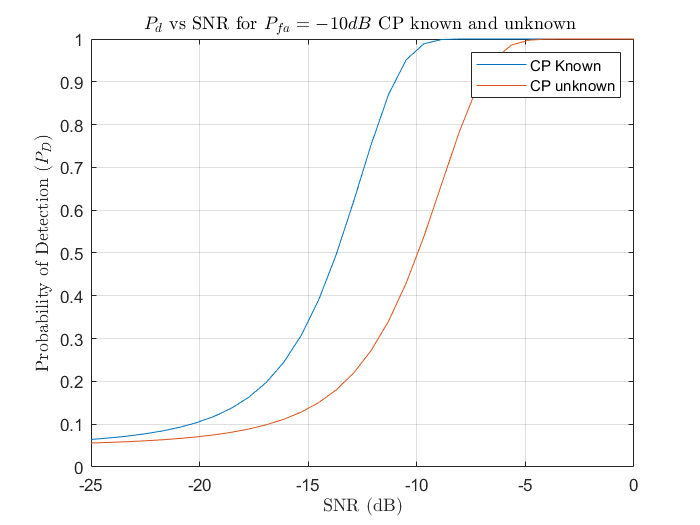

rho1 = zeros(length(SNR_dB),1);
for i=1:length(SNR_dB)
    rho1(i) = (Tc)/(Td+Tc)*(db_to_lin(SNR_dB(i)))/(1+db_to_lin(SNR_dB(i)));
end
ELn_H0 =  zeros(length(SNR_dB),1);
ELn_H1 =  zeros(length(SNR_dB),1);
for i=1:length(SNR_dB)
    ELn_H0(i) = -M.*log10(1-rho1(i)^2)-2*M*((rho1(i)^2)/(1-rho1(i) ^ 2));

    ELn_H1(i) = -M.*log10(1-rho1(i)^2);
end

EKs_H0 =  zeros(length(SNR_dB),1);
EKs_H1 =  zeros(length(SNR_dB),1);

for i=1:length(SNR_dB)
   EKs_H0(i) = (Pfa.*log10(A)+(1-Pfa).*log10(B))./( ELn_H0(i));
   EKs_H1(i) = ( (1-beta).*log10(A) + beta.*log10(B))/(ELn_H1(i));
end
Km = max( EKs_H0,EKs_H1);

rhon = rho1;
Kf = zeros(length(SNR_dB),1);
for i=1:length(SNR_dB)
    Kf(i) = (erfcinv(2*Pfa) - (1-rho1(i).^2).*erfcinv(2*Pd) ).^2./(M*rho1(i) .^ 2);
end
RE = Kf./Km(:,1);

figure
plot(SNR_dB,RE,'r--')
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("Average Sample Number (ASN)",'interpreter','latex');
title(" $P_{fa} = 0.05$ , $P_D = 0.95$ ",'interpreter','latex');
ylim([0,4])

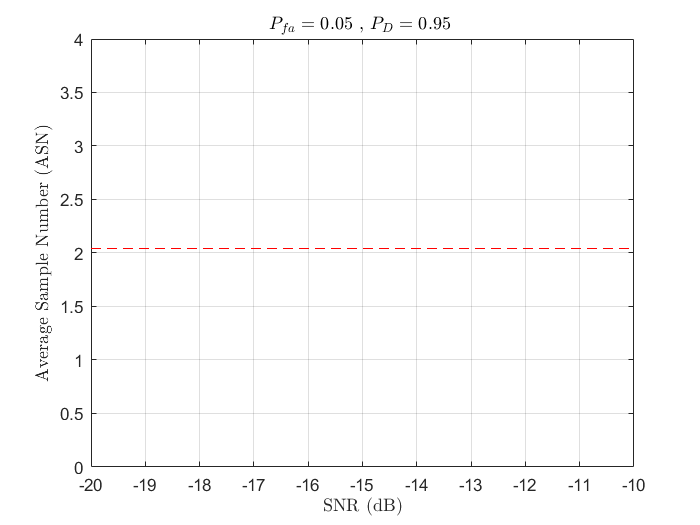

% OFDM system parameters
numBlocks = 100;        % Number of OFDM blocks
IFFTSize = 32;          % IFFT size
cyclicPrefix = 8;       % Cyclic prefix size
numSymbols = IFFTSize * numBlocks;

% Modulation parameters
M = 16;                 % QAM order

% SNR value
EbNo = -10;             % SNR value in dB

% Varying Pfa values
Pfa = 0:0.05:1;

% Initialize arrays for Pd (probability of detection)
Pd = zeros(size(Pfa));

% Generate random binary data
data = randi([0, 1], numSymbols * log2(M), 1);

% Reshape binary data into symbols

dataSymbols = reshape(data, log2(M), []).';

% Map bits to constellation points
constellation = qammod(0:M-1, M);
modulatedSymbols = constellation(bin2dec(num2str(dataSymbols))+1);

% Reshape modulated symbols into blocks
modulatedSymbols = reshape(modulatedSymbols, IFFTSize, numBlocks);

% Perform IFFT on each block
timeDomainSignal = ifft(modulatedSymbols, IFFTSize);

% Add cyclic prefix
timeDomainSignalWithCP = [timeDomainSignal(end-cyclicPrefix+1:end, :); timeDomainSignal];

% Convert time-domain signal to serial stream
transmittedSignal = timeDomainSignalWithCP(:);

% Calculate noise variance for AWGN component
snr = 10^(EbNo/10);                           % Convert EbNo from dB to linear scale
awgnNoiseVar = 1/(2*snr);                      % Calculate AWGN noise variance
sigma_shadowing = 3;
% Generate shadowing component
shadowing_dB = randn(size(transmittedSignal)) * sigma_shadowing;
shadowing = 10.^(shadowing_dB/10);

% Add AWGN and shadowing to the transmitted signal
receivedSignal = transmittedSignal .* shadowing + sqrt(awgnNoiseVar/2) * (randn(size(transmittedSignal)) + 1i * randn(size(transmittedSignal)));

% Reshape received signal into blocks with cyclic prefix
receivedSignalWithCP = reshape(receivedSignal, IFFTSize+cyclicPrefix, []);

% Remove cyclic prefix
receivedSignal = receivedSignalWithCP(cyclicPrefix+1:end, :);

% Perform FFT on each block
receivedSymbols = fft(receivedSignal, IFFTSize);

% Reshape received symbols into a serial stream
receivedSymbols = receivedSymbols(:);

% Calculate detection threshold based on Pfa
threshold = qfuncinv(Pfa) * sqrt(2 * awgnNoiseVar);

% Simulate the OFDM system for each Pfa value
for i = 1:length(Pfa)
    % Calculate probability of detection (Pd)
    detections = sum(abs(receivedSymbols) > threshold(i));
    Pd(i) = detections / numSymbols;
end

% Plot the ROC curve
figure;
plot(Pfa, Pd, 'b-o');
xlabel('Probability of False Alarm (Pfa)');
ylabel('Probability of Detection (Pd)');
title(['Receiver Operating Characteristic (ROC) Curve for OFDM System at SNR = ' num2str(EbNo) ' dB with Shadowing']);
grid on;


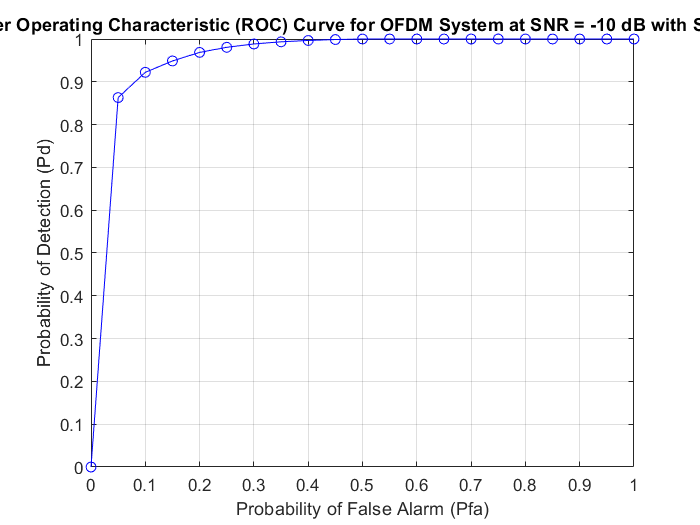

function [b_tx] =  bit_gen( pkt_size, sample_per_smbl)
    %rng(1)
    k = log2(sample_per_smbl);
    randomtemp = randi(2,k*pkt_size,1) - 1;
    b_tx = reshape(randomtemp,pkt_size,k);
end